datadir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/data/Spiralssize3000nclusters2noise0.00.mat';
data = block_data.loadProperties(datadir);
savedir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/bag/';


Scheme = '';
GenParam = '';
bag1 = block_bag({'Scheme',Scheme,'GenParam',GenParam},data);

Error using block_bag (line 20)
Error! Scheme is not specified. Specify Scheme: 1 for Random positive ratio, 2 for Uniform positive ratio

Scheme = 1;
GenParam = '';
bag2 = block_bag({'Scheme',Scheme,'GenParam',GenParam},data);

Bags with 150 positive bags,150 negative bags,and randomness 0 are generated


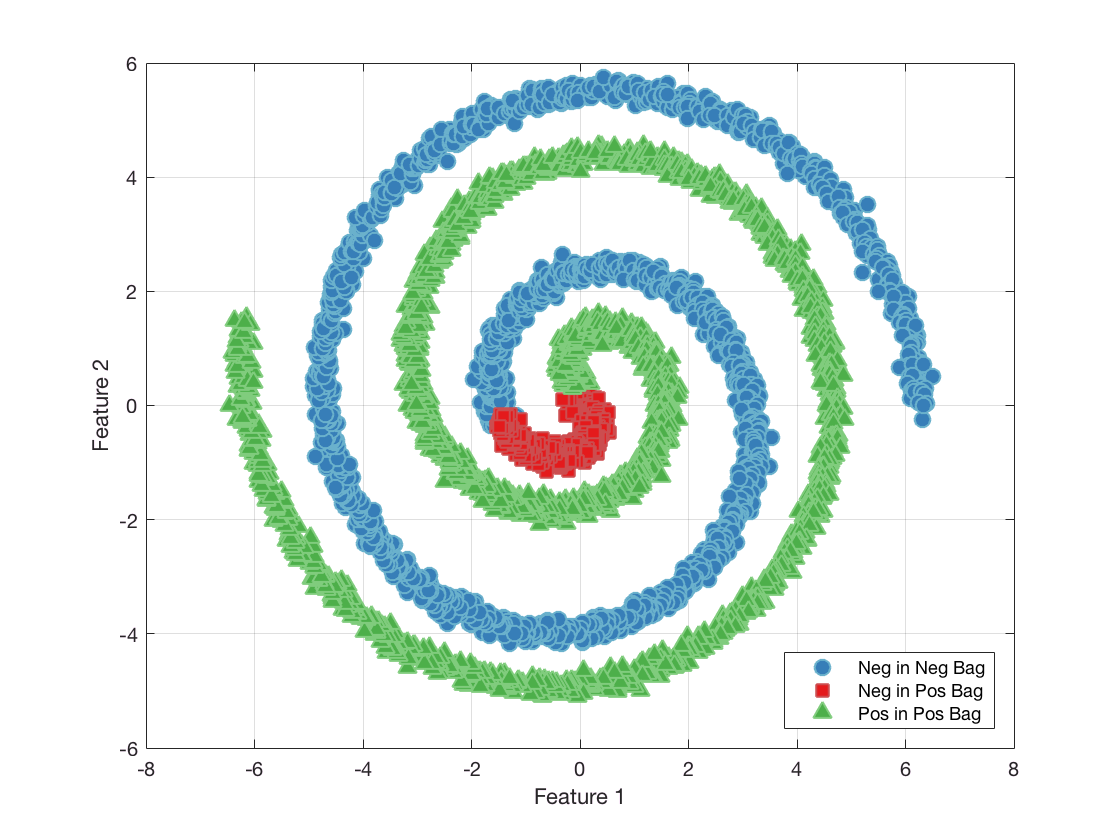

bag2.PlotBag();

block_bag.saveProperties(bag2,savedir);

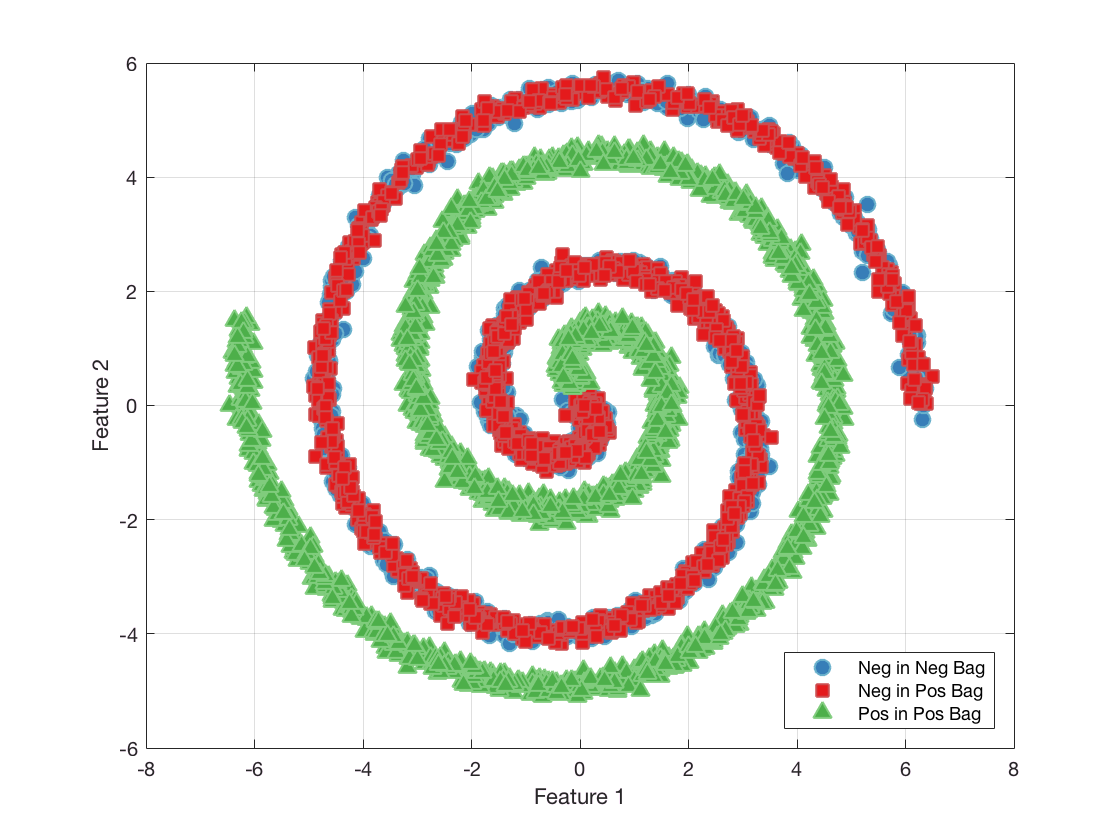

Scheme = 1;
GenParam.nPosBag = 400;
GenParam.nNegBag = 400;
GenParam.Random = 1;
bag3 = block_bag({'Scheme',Scheme,'GenParam',GenParam},data);
bag3.PlotBag();

block_bag.saveProperties(bag3,savedir);

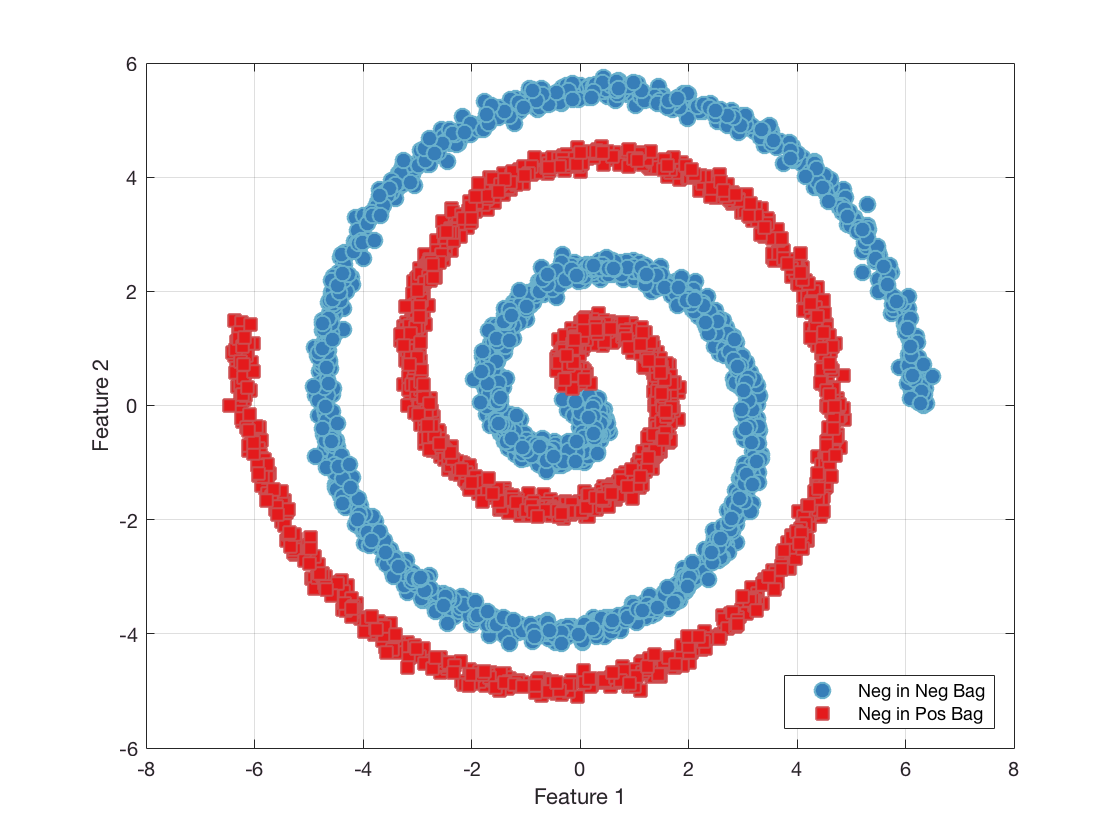

Scheme = 2;
GenParam.nPosBag = 100;
GenParam.nNegBag = 100;
GenParam.Random = 1;
GenParam.PosPortion = 20;
GenParam.BagSize = 20;
bag4 = block_bag({'Scheme',Scheme,'GenParam',GenParam},data);
bag4.PlotBag();

block_bag.saveProperties(bag4,savedir);

Scheme = 2;
GenParam = '';
bag4 = block_bag({'Scheme',Scheme,'GenParam',GenParam},data);

Bags with 150 positive bags,150 negative bags,and randomness 0 are generated
Postive portion 50/50


Error using block_bag/GenBag (line 85)
Error! Scheme 2 requires number of positive instance in positive bags smaller than total positive instances in data block

Error in block_bag (line 24)
                self = s

bag4.PlotBag();
block_bag.saveProperties(bag4,savedir);